# Load data

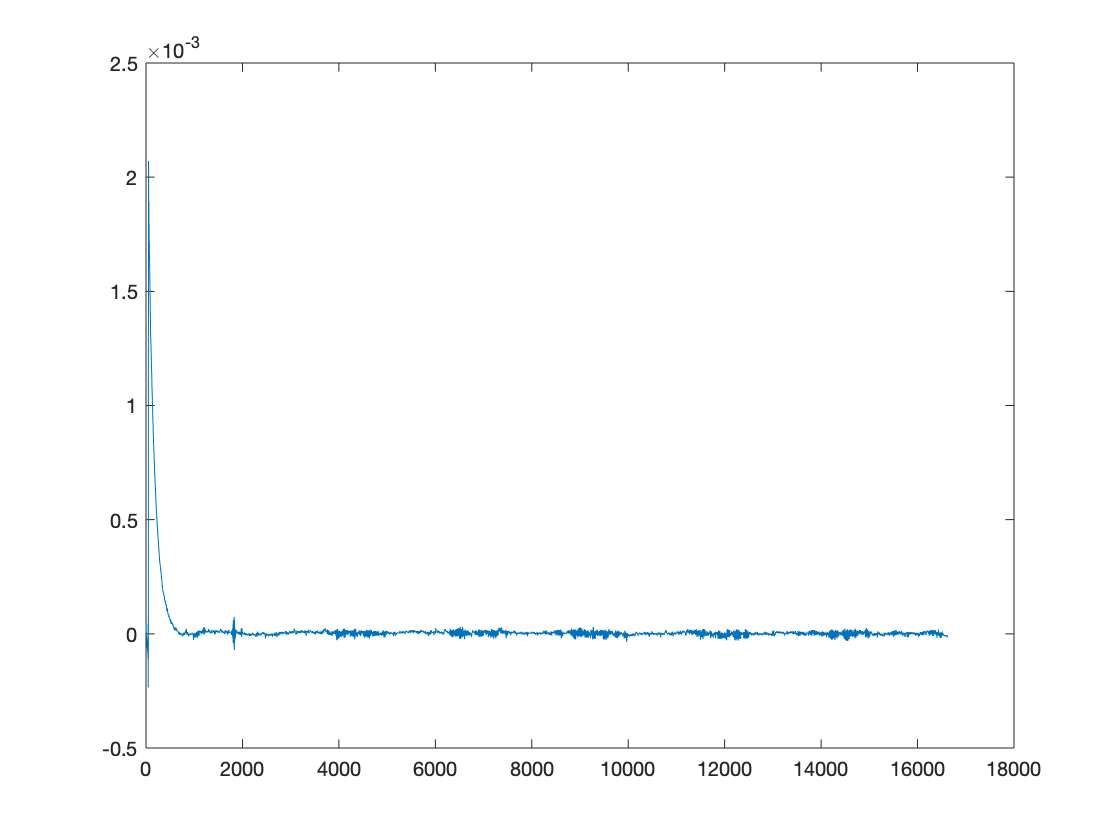

addpath './data/test alpha 5s'
ALLEEG = load('5sopen_close.mat').ALLEEG; % EEGLAB format
sig = ALLEEG.data;
plot(sig)

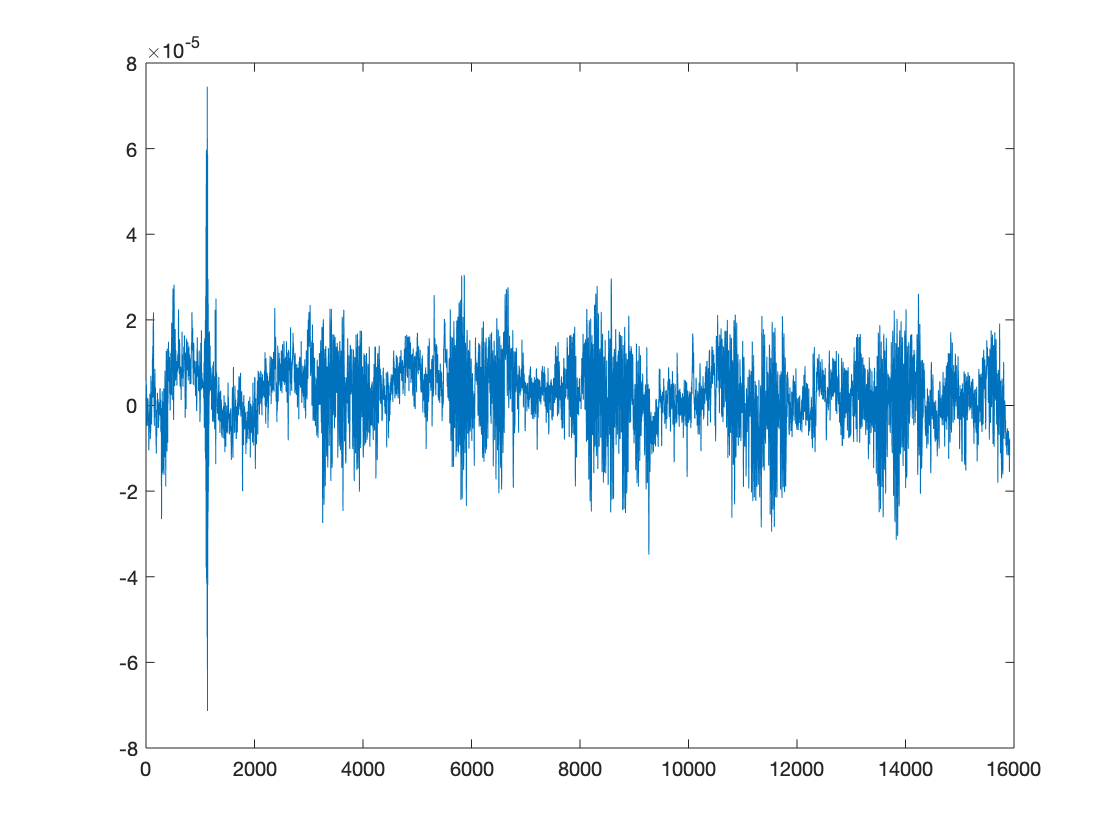

start = 700; 
plot(sig(start:end))

## Load tool

addpath './tools/spectral'
help plot_spectrogram

  This function allow us to plot the spectrogram
 
 IN:
    data:           input data
    startgr:        the start point of the data
    chan:           channel (default 1)
    axes_handles:   plot in figure
 OUT:
    figure plot the spectrogram of the channal of the data
 
 Exmaple: 
    % Plot data 'a' started from sample 510
    plot_spectrogram(a,510)



## Visualization

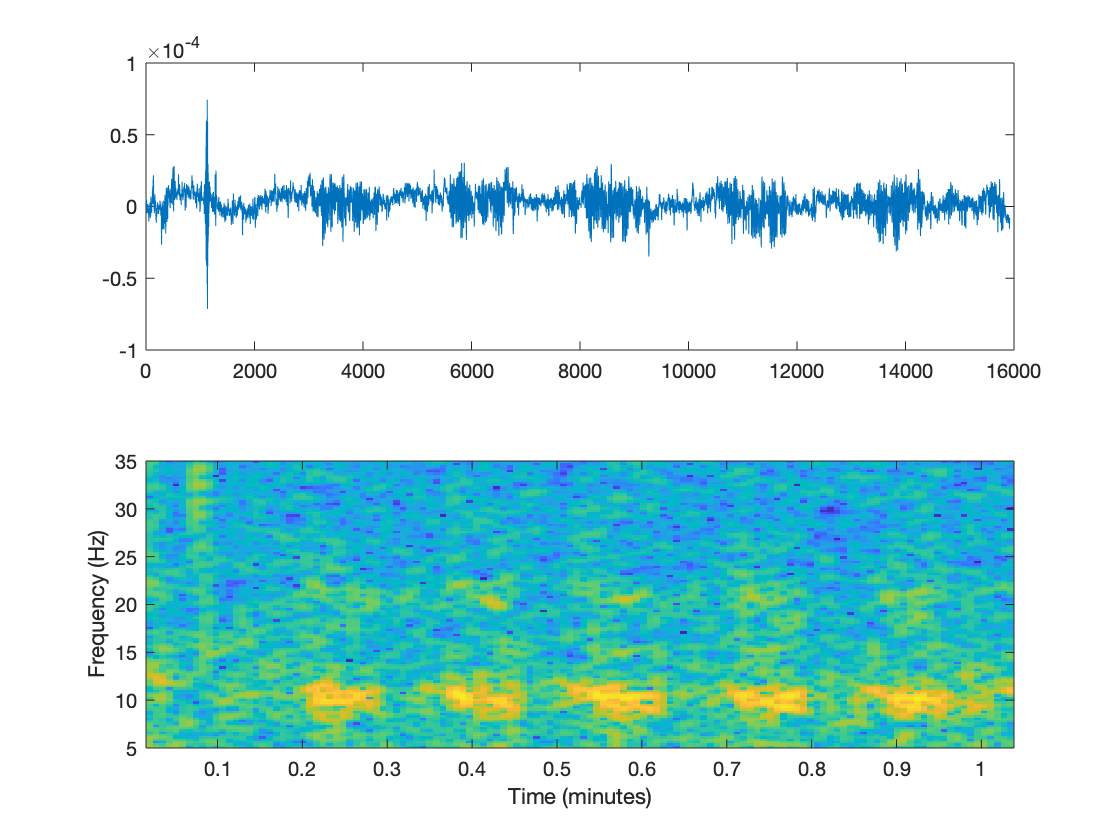

figure;
start = 700;
subplot(2,1,1), plot(sig(start:end))
ax = subplot(2,1,2); plot_spectrogram(sig, start, 1, ax), colorbar('Off');

## Visualization wrt events

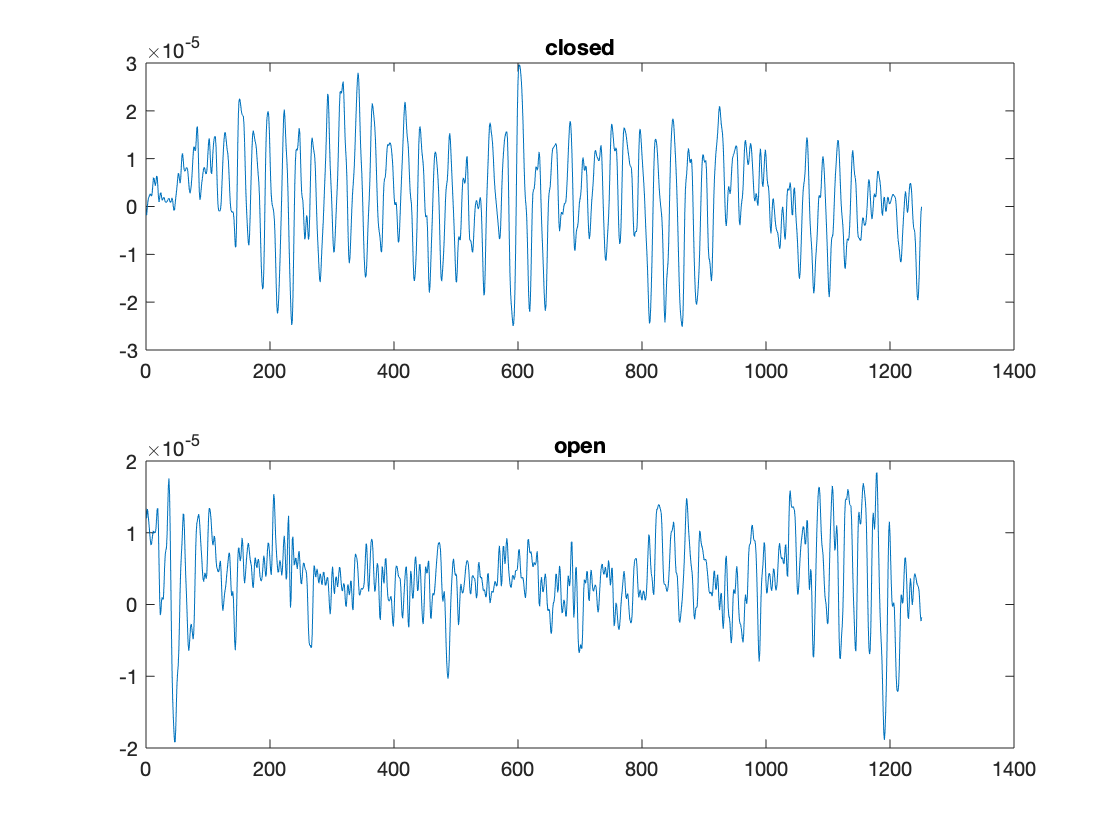

event = ALLEEG.event;
event1 = event(5).latency; % odd: closed, even: open
window = ALLEEG.srate*5;

closed_sample = sig(event1:(event1+window));
open_sample = sig((event1-window):event1);
figure;
subplot(2,1,1), plot(closed_sample), title('closed')
subplot(2,1,2), plot(open_sample), title('open')